## Program args

PlotData = false;

## 导入数据

在新环境下运行前，可能需要重新选择一下数据文件。

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 512);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["x0", "x0_012272", "x0_024544", "x0_036816", "x0_049087", "x0_061359", "x0_073631", "x0_085903", "x0_098175", "x0_11045", "x0_12272", "x0_13499", "x0_14726", "x0_15953", "x0_17181", "x0_18408", "x0_19635", "x0_20862", "x0_22089", "x0_23317", "x0_24544", "x0_25771", "x0_26998", "x0_28225", "x0_29452", "x0_3068", "x0_31907", "x0_33134", "x0_34361", "x0_35588", "x0_36816", "x0_38043", "x0_3927", "x0_40497", "x0_41724", "x0_42951", "x0_44179", "x0_45406", "x0_46633", "x0_4786", "x0_49087", "x0_50315", "x0_51542", "x0_52769", "x0_53996", "x0_55223", "x0_56451", "x0_57678", "x0_58905", "x0_60132", "x0_61359", "x0_62586", "x0_63814", "x0_65041", "x0_66268", "x0_67495", "x0_68722", "x0_69949", "x0_71177", "x0_72404", "x0_73631", "x0_74858", "x0_76085", "x0_77313", "x0_7854", "x0_79767", "x0_80994", "x0_82221", "x0_83449", "x0_84676", "x0_85903", "x0_8713", "x0_88357", "x0_89585", "x0_90812", "x0_92039", "x0_93266", "x0_94493", "x0_9572", "x0_96948", "x0_98175", "x0_99402", "x1_0063", "x1_0186", "x1_0308", "x1_0431", "x1_0554", "x1_0676", "x1_0799", "x1_0922", "x1_1045", "x1_1167", "x1_129", "x1_1413", "x1_1536", "x1_1658", "x1_1781", "x1_1904", "x1_2026", "x1_2149", "x1_2272", "x1_2395", "x1_2517", "x1_264", "x1_2763", "x1_2885", "x1_3008", "x1_3131", "x1_3254", "x1_3376", "x1_3499", "x1_3622", "x1_3744", "x1_3867", "x1_399", "x1_4113", "x1_4235", "x1_4358", "x1_4481", "x1_4604", "x1_4726", "x1_4849", "x1_4972", "x1_5094", "x1_5217", "x1_534", "x1_5462", "x1_5585", "x1_5708", "x1_5831", "x1_5953", "x1_6076", "x1_6199", "x1_6322", "x1_6444", "x1_6567", "x1_669", "x1_6812", "x1_6935", "x1_7058", "x1_7181", "x1_7303", "x1_7426", "x1_7549", "x1_7671", "x1_7794", "x1_7917", "x1_804", "x1_8162", "x1_8285", "x1_8408", "x1_8531", "x1_8653", "x1_8776", "x1_8899", "x1_9021", "x1_9144", "x1_9267", "x1_9389", "x1_9512", "x1_9635", "x1_9758", "x1_988", "x2_0003", "x2_0126", "x2_0248", "x2_0371", "x2_0494", "x2_0617", "x2_0739", "x2_0862", "x2_0985", "x2_1108", "x2_123", "x2_1353", "x2_1476", "x2_1598", "x2_1721", "x2_1844", "x2_1967", "x2_2089", "x2_2212", "x2_2335", "x2_2458", "x2_258", "x2_2703", "x2_2826", "x2_2948", "x2_3071", "x2_3194", "x2_3316", "x2_3439", "x2_3562", "x2_3685", "x2_3807", "x2_393", "x2_4053", "x2_4175", "x2_4298", "x2_4421", "x2_4544", "x2_4666", "x2_4789", "x2_4912", "x2_5035", "x2_5157", "x2_528", "x2_5403", "x2_5525", "x2_5648", "x2_5771", "x2_5894", "x2_6016", "x2_6139", "x2_6262", "x2_6385", "x2_6507", "x2_663", "x2_6753", "x2_6875", "x2_6998", "x2_7121", "x2_7243", "x2_7366", "x2_7489", "x2_7612", "x2_7734", "x2_7857", "x2_798", "x2_8102", "x2_8225", "x2_8348", "x2_8471", "x2_8593", "x2_8716", "x2_8839", "x2_8962", "x2_9084", "x2_9207", "x2_933", "x2_9452", "x2_9575", "x2_9698", "x2_9821", "x2_9943", "x3_0066", "x3_0189", "x3_0311", "x3_0434", "x3_0557", "x3_068", "x3_0802", "x3_0925", "x3_1048", "x3_117", "x3_1293", "x3_1416", "x3_1539", "x3_1661", "x3_1784", "x3_1907", "x3_2029", "x3_2152", "x3_2275", "x3_2398", "x3_252", "x3_2643", "x3_2766", "x3_2889", "x3_3011", "x3_3134", "x3_3257", "x3_3379", "x3_3502", "x3_3625", "x3_3748", "x3_387", "x3_3993", "x3_4116", "x3_4238", "x3_4361", "x3_4484", "x3_4607", "x3_4729", "x3_4852", "x3_4975", "x3_5097", "x3_522", "x3_5343", "x3_5466", "x3_5588", "x3_5711", "x3_5834", "x3_5957", "x3_6079", "x3_6202", "x3_6325", "x3_6447", "x3_657", "x3_6693", "x3_6816", "x3_6938", "x3_7061", "x3_7184", "x3_7306", "x3_7429", "x3_7552", "x3_7675", "x3_7797", "x3_792", "x3_8043", "x3_8165", "x3_8288", "x3_8411", "x3_8534", "x3_8656", "x3_8779", "x3_8902", "x3_9024", "x3_9147", "x3_927", "x3_9393", "x3_9515", "x3_9638", "x3_9761", "x3_9884", "x4_0006", "x4_0129", "x4_0252", "x4_0374", "x4_0497", "x4_062", "x4_0743", "x4_0865", "x4_0988", "x4_1111", "x4_1233", "x4_1356", "x4_1479", "x4_1602", "x4_1724", "x4_1847", "x4_197", "x4_2092", "x4_2215", "x4_2338", "x4_2461", "x4_2583", "x4_2706", "x4_2829", "x4_2951", "x4_3074", "x4_3197", "x4_332", "x4_3442", "x4_3565", "x4_3688", "x4_3811", "x4_3933", "x4_4056", "x4_4179", "x4_4301", "x4_4424", "x4_4547", "x4_4669", "x4_4792", "x4_4915", "x4_5038", "x4_516", "x4_5283", "x4_5406", "x4_5529", "x4_5651", "x4_5774", "x4_5897", "x4_6019", "x4_6142", "x4_6265", "x4_6388", "x4_651", "x4_6633", "x4_6756", "x4_6879", "x4_7001", "x4_7124", "x4_7247", "x4_7369", "x4_7492", "x4_7615", "x4_7737", "x4_786", "x4_7983", "x4_8106", "x4_8228", "x4_8351", "x4_8474", "x4_8597", "x4_8719", "x4_8842", "x4_8965", "x4_9087", "x4_921", "x4_9333", "x4_9455", "x4_9578", "x4_9701", "x4_9824", "x4_9946", "x5_0069", "x5_0192", "x5_0315", "x5_0437", "x5_056", "x5_0683", "x5_0805", "x5_0928", "x5_1051", "x5_1174", "x5_1296", "x5_1419", "x5_1542", "x5_1665", "x5_1787", "x5_191", "x5_2033", "x5_2155", "x5_2278", "x5_2401", "x5_2523", "x5_2646", "x5_2769", "x5_2892", "x5_3014", "x5_3137", "x5_326", "x5_3383", "x5_3505", "x5_3628", "x5_3751", "x5_3873", "x5_3996", "x5_4119", "x5_4242", "x5_4364", "x5_4487", "x5_461", "x5_4732", "x5_4855", "x5_4978", "x5_5101", "x5_5223", "x5_5346", "x5_5469", "x5_5591", "x5_5714", "x5_5837", "x5_596", "x5_6082", "x5_6205", "x5_6328", "x5_6451", "x5_6573", "x5_6696", "x5_6819", "x5_6941", "x5_7064", "x5_7187", "x5_7309", "x5_7432", "x5_7555", "x5_7678", "x5_78", "x5_7923", "x5_8046", "x5_8169", "x5_8291", "x5_8414", "x5_8537", "x5_8659", "x5_8782", "x5_8905", "x5_9028", "x5_915", "x5_9273", "x5_9396", "x5_9519", "x5_9641", "x5_9764", "x5_9887", "x6_0009", "x6_0132", "x6_0255", "x6_0377", "x6_05", "x6_0623", "x6_0746", "x6_0868", "x6_0991", "x6_1114", "x6_1236", "x6_1359", "x6_1482", "x6_1605", "x6_1727", "x6_185", "x6_1973", "x6_2096", "x6_2218", "x6_2341", "x6_2464", "x6_2586", "x6_2709"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.LeadingDelimitersRule = "ignore";

% Import the data
x = readtable("D:\source\repos\Chiahwa\HwaQuantum\HwaQuantum\result\x.txt", opts);

% Convert to output type
x = table2array(x);

% Clear temporary variables
clear opts

% Display results
x

x =          0    0.0123    0.0245    0.0368    0.0491    0.0614    0.0736    0.0859    0.0982    0.1104    0.1227    0.1350    0.1473    0.1595    0.1718    0.1841    0.1963    0.2086    0.2209    0.2332    0.2454    0.2577    0.2700    0.2823    0.2945    0.3068    0.3191    0.3313    0.3436    0.3559    0.3682    0.3804    0.3927    0.4050    0.4172    0.4295    0.4418    0.4541    0.4663    0.4786    0.4909    0.5031    0.5154    0.5277    0.5400    0.5522    0.5645    0.5768    0.5890    0.6013


% Set up the Import Options and import the data
opts2 = delimitedTextImportOptions("NumVariables", 512);

% Specify range and delimiter
opts2.DataLines = [1, Inf];
opts2.Delimiter = " ";

% Specify column names and types
opts2.VariableNames = ["x2", "x2_0245", "x2_0491", "x2_0736", "x2_098", "x2_1224", "x2_1467", "x2_171", "x2_1951", "x2_2191", "x2_243", "x2_2667", "x2_2903", "x2_3137", "x2_3369", "x2_3599", "x2_3827", "x2_4052", "x2_4276", "x2_4496", "x2_4714", "x2_4929", "x2_5141", "x2_535", "x2_5556", "x2_5758", "x2_5957", "x2_6152", "x2_6344", "x2_6532", "x2_6716", "x2_6895", "x2_7071", "x2_7243", "x2_741", "x2_7572", "x2_773", "x2_7883", "x2_8032", "x2_8176", "x2_8315", "x2_8449", "x2_8577", "x2_8701", "x2_8819", "x2_8932", "x2_904", "x2_9142", "x2_9239", "x2_933", "x2_9415", "x2_9495", "x2_9569", "x2_9638", "x2_97", "x2_9757", "x2_9808", "x2_9853", "x2_9892", "x2_9925", "x2_9952", "x2_9973", "x2_9988", "x2_9997", "x3", "x2_1", "x2_2", "x2_3", "x2_4", "x2_5", "x2_6", "x2_7", "x2_8", "x2_9", "x2_10", "x2_11", "x2_12", "x2_13", "x2_14", "x2_15", "x2_16", "x2_17", "x2_18", "x2_19", "x2_20", "x2_21", "x2_22", "x2_23", "x2_24", "x2_25", "x2_26", "x2_27", "x2_28", "x2_29", "x2_30", "x2_31", "x2_32", "x2_33", "x2_34", "x2_35", "x2_36", "x2_37", "x2_38", "x2_39", "x2_40", "x2_41", "x2_42", "x2_43", "x2_44", "x2_45", "x2_46", "x2_47", "x2_48", "x2_49", "x2_50", "x2_51", "x2_52", "x2_53", "x2_54", "x2_55", "x2_56", "x2_57", "x2_58", "x2_59", "x2_60", "x2_61", "x2_62", "x2_63", "x1", "x1_9755", "x1_9509", "x1_9264", "x1_902", "x1_8776", "x1_8533", "x1_829", "x1_8049", "x1_7809", "x1_757", "x1_7333", "x1_7097", "x1_6863", "x1_6631", "x1_6401", "x1_6173", "x1_5948", "x1_5724", "x1_5504", "x1_5286", "x1_5071", "x1_4859", "x1_465", "x1_4444", "x1_4242", "x1_4043", "x1_3848", "x1_3656", "x1_3468", "x1_3284", "x1_3105", "x1_2929", "x1_2757", "x1_2591", "x1_2428", "x1_227", "x1_2116", "x1_1968", "x1_1824", "x1_1685", "x1_1551", "x1_1423", "x1_1299", "x1_1181", "x1_1068", "x1_096", "x1_0858", "x1_0761", "x1_067", "x1_0585", "x1_0505", "x1_0431", "x1_0362", "x1_03", "x1_0243", "x1_0192", "x1_0147", "x1_0108", "x1_0075", "x1_0048", "x1_0027", "x1_0012", "x1_0003", "x4", "x1_1", "x1_2", "x1_3", "x1_4", "x1_5", "x1_6", "x1_7", "x1_8", "x1_9", "x1_10", "x1_11", "x1_12", "x1_13", "x1_14", "x1_15", "x1_16", "x1_17", "x1_18", "x1_19", "x1_20", "x1_21", "x1_22", "x1_23", "x1_24", "x1_25", "x1_26", "x1_27", "x1_28", "x1_29", "x1_30", "x1_31", "x1_32", "x1_33", "x1_34", "x1_35", "x1_36", "x1_37", "x1_38", "x1_39", "x1_40", "x1_41", "x1_42", "x1_43", "x1_44", "x1_45", "x1_46", "x1_47", "x1_48", "x1_49", "x1_50", "x1_51", "x1_52", "x1_53", "x1_54", "x1_55", "x1_56", "x1_57", "x1_58", "x1_59", "x1_60", "x1_61", "x1_62", "x1_63", "x5", "x2_64", "x2_65", "x2_66", "x2_67", "x2_68", "x2_69", "x2_70", "x2_71", "x2_72", "x2_73", "x2_74", "x2_75", "x2_76", "x2_77", "x2_78", "x2_79", "x2_80", "x2_81", "x2_82", "x2_83", "x2_84", "x2_85", "x2_86", "x2_87", "x2_88", "x2_89", "x2_90", "x2_91", "x2_92", "x2_93", "x2_94", "x2_95", "x2_96", "x2_98", "x2_99", "x2_100", "x2_101", "x2_102", "x2_103", "x2_104", "x2_105", "x2_106", "x2_107", "x2_108", "x2_109", "x2_110", "x2_111", "x2_112", "x2_113", "x2_114", "x2_115", "x2_116", "x2_117", "x2_118", "x2_119", "x2_120", "x2_121", "x2_122", "x2_123", "x2_124", "x2_125", "x2_126", "x2_127", "x6", "x2_128", "x2_129", "x2_130", "x2_131", "x2_132", "x2_133", "x2_134", "x2_135", "x2_136", "x2_137", "x2_138", "x2_139", "x2_140", "x2_141", "x2_142", "x2_143", "x2_144", "x2_145", "x2_146", "x2_147", "x2_148", "x2_149", "x2_150", "x2_151", "x2_152", "x2_153", "x2_154", "x2_155", "x2_156", "x2_157", "x2_158", "x2_159", "x2_160", "x2_161", "x2_162", "x2_163", "x2_164", "x2_165", "x2_166", "x2_167", "x2_168", "x2_169", "x2_170", "x2_172", "x2_173", "x2_174", "x2_175", "x2_176", "x2_177", "x2_178", "x2_179", "x2_180", "x2_181", "x2_182", "x2_183", "x2_184", "x2_185", "x2_186", "x2_187", "x2_188", "x2_189", "x2_190", "x2_191", "x7", "x1_64", "x1_65", "x1_66", "x1_67", "x1_68", "x1_69", "x1_70", "x1_71", "x1_72", "x1_73", "x1_74", "x1_75", "x1_76", "x1_77", "x1_78", "x1_79", "x1_80", "x1_81", "x1_82", "x1_83", "x1_84", "x1_85", "x1_86", "x1_87", "x1_88", "x1_89", "x1_90", "x1_91", "x1_92", "x1_93", "x1_94", "x1_95", "x1_96", "x1_97", "x1_98", "x1_99", "x1_100", "x1_101", "x1_102", "x1_103", "x1_104", "x1_105", "x1_106", "x1_107", "x1_108", "x1_109", "x1_110", "x1_111", "x1_112", "x1_113", "x1_114", "x1_115", "x1_116", "x1_117", "x1_118", "x1_119", "x1_120", "x1_121", "x1_122", "x1_123", "x1_124", "x1_125", "x1_126", "x8", "x1_127", "x1_128", "x1_129", "x1_130", "x1_131", "x1_132", "x1_133", "x1_134", "x1_135", "x1_136", "x1_137", "x1_138", "x1_139", "x1_140", "x1_141", "x1_142", "x1_143", "x1_144", "x1_145", "x1_146", "x1_147", "x1_148", "x1_149", "x1_150", "x1_151", "x1_152", "x1_153", "x1_154", "x1_155", "x1_156", "x1_157", "x1_158", "x1_159", "x1_160", "x1_161", "x1_162", "x1_163", "x1_164", "x1_165", "x1_166", "x1_167", "x1_168", "x1_169", "x1_170", "x1_171", "x1_172", "x1_173", "x1_174", "x1_175", "x1_176", "x1_177", "x1_178", "x1_179", "x1_180", "x1_181", "x1_182", "x1_183", "x1_184", "x1_185", "x1_186", "x1_187", "x1_188", "x1_189"];
opts2.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";
opts2.ConsecutiveDelimitersRule = "join";
opts2.LeadingDelimitersRule = "ignore";

% Import the data
u = readtable("D:\source\repos\Chiahwa\HwaQuantum\HwaQuantum\result\u.txt", opts2);

% Convert to output type
u = table2array(u);

% Clear temporary variables
clear opts2

% Import data from text file
params = readtable("D:\source\repos\Chiahwa\HwaQuantum\HwaQuantum\result\params.txt");

% Display results
params

params = 1×9 table
    c      L       lambda    offset     dt     nqubits    nsteps    noise_type    noise_p
    _    ______    ______    ______    ____    _______    ______    __________    _______

    1    6.2832      64        2       0.15       9         30          3          0.05  


%x=x'
% u=u-params.offset;
t=params.dt*(0:params.nsteps);
noise_type_str = ["BITFLIP", "DEPOLARIZING", "DEPHASING", "DAMPING"];

导入的数据

if PlotData
    figure;hold on;
    for i=0:params.nsteps
        ui=u(i+1,:);
        plot(x,ui, 'DisplayName',strcat('u(t=',num2str(params.dt*i),')'));
    end
    legend;
    box on;
    grid minor;
    title('Noisy data')
end

## 对采样进行平滑（Local quadratic regression）


smoothed = zeros(params.nsteps+1,2^params.nqubits);
for i=0:params.nsteps
    ui=u(i+1,:);

% Smooth input data
smoothed_ui = smoothdata(ui,"loess",1,"SamplePoints",x);
    smoothed(i+1,:)=smoothed_ui;    
    
end
if PlotData
    figure;hold on;
    for i=0:params.nsteps
        plot(x,u(i+1,:), 'DisplayName',strcat('u(t=',num2str(params.dt*i),')'));
        plot(x,smoothed_ui,'DisplayName',strcat('smoothed(t=',num2str(params.dt*i),')'));
    end
    legend;
    box on;
    grid minor;
    title('Noisy and LOESS-smoothed data')
end

## 用扩散型模型对采样进行拟合

### 对每个 t, 拟合 u

对每个时刻t，拟合模型$u(x,t;D,E,F,G)=D\sin(E(x-Ft))+G$

modelEq = '$\ u(x,t;D,E,F,G)=D\sin(E(x-Ft))+G$';
function v = diffusion_model(p,x,t,lambda)
    D=p(1);
    E=p(2);
    F=p(3);
    G=p(4);
    v = D*sin(E*(x-F*t))+G ;
end
% unused
function error = residual_u(p,x,u_observed,lambda,c,t)
    v_predicted = diffusion_model(p,x,lambda,c,t);
    error = sum((u_observed - v_predicted).^2);
end

优化求解

D_opt = zeros(params.nsteps,1);
E_opt = zeros(params.nsteps,1);
F_opt = zeros(params.nsteps,1);
G_opt = zeros(params.nsteps,1);
% resnorm is the squared 2-norm of the residual(残差) at x: sum((fun(x,xdata)-ydata).^2).
resnorms = zeros(params.nsteps,1);
for i = 1:params.nsteps
    ui = u(i+1,:);
    % D E F G
    p_initial = [1.0, params.lambda, params.c,  params.offset];
    lb =        [0,   0,             0,         -Inf         ];
    ub =        [Inf, Inf,           2*pi,      Inf          ];
    options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
    [p_opt, resnorms(i)]=lsqcurvefit(@(p,x)diffusion_model(p,x,params.dt*(i),params.lambda), p_initial, x, ui, lb, ub, options);
    D_opt(i) = p_opt(1);
    E_opt(i) = p_opt(2);
    F_opt(i) = p_opt(3);
    G_opt(i) = p_opt(4);
end


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          5          0.989822                             14.9
     1         10         0.0215572        0.056838            0.776      
     2         15         0.0189212      0.00328993          0.00262      
     3         20         0.0189212     1.11911e-05          7.3e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                              

ModelArgs = table(D_opt,E_opt,F_opt,G_opt,resnorms)

ModelArgs = 30×5 table
     D_opt     E_opt     F_opt     G_opt     resnorms
    _______    _____    _______    ______    ________

    0.94173     64      0.99999    2.0141    0.018921
    0.88889     64            1     2.026     0.05702
    0.84061     64      0.99999    2.0363     0.10026
    0.79627     64            1    2.0452      0.1412
    0.75537     64      0.99999    2.0529     0.17507
    0.71749     64            1    2.0597     0.20099
    0.68233     64            1    2.0656     0.22086
    0.64959     64            1    2.0709     0.23482
    0.61906     64            1    2.0756     0.24299
    0.59051     64            1    2.0797     0.24612
    0.56378     64            1    2.0834     0.24537
    0.53872     64            1    2.0867     0.24193
    0.51518     64            1    2.0897      0.2

### 拟合 D-t 曲线

对每个时刻t，拟合模型$D(t)=Pe^{Qt}+R$

modelEq_D = '$\ D(t)=Pe^{Qt}+R$';
function v = D_model(p,t)
    P=p(1);
    Q=p(2);
    R=p(3);
    v = P*exp(Q*t)+R ;
end

function error = residual_D(p,t,D_observed)
    D_predicted = D_model(p,t);
    error = sum((D_observed-D_predicted).^2);
end

优化求解

% resnorm is the squared 2-norm of the residual(残差) at x: sum((fun(x,xdata)-ydata).^2).
%           [P    Q                 R    ]
p_initial = [1.0, -0.5, 0.1 ];
lb =        [0,   -Inf,             -Inf ];
ub =        [Inf, 0,                Inf  ];
options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
[p_opt, resnorm_D]=lsqcurvefit(@(p,t)D_model(p,t), p_initial, t(2:end)', D_opt, lb, ub, options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4         0.0826892                            0.805
     1          8        0.00148833        0.199447           0.0522      
     2         12       0.000384994       0.0742051           0.0549      
     3         16       0.000192726       0.0233898          0.00781      
     4         20       0.000190072       0.0013232         1.22e-05      
     5         24       0.000190072     1.74473e-05         2.56e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

P=p_opt(1);
Q=p_opt(2);
R=p_opt(3);

单个时刻的解和模型

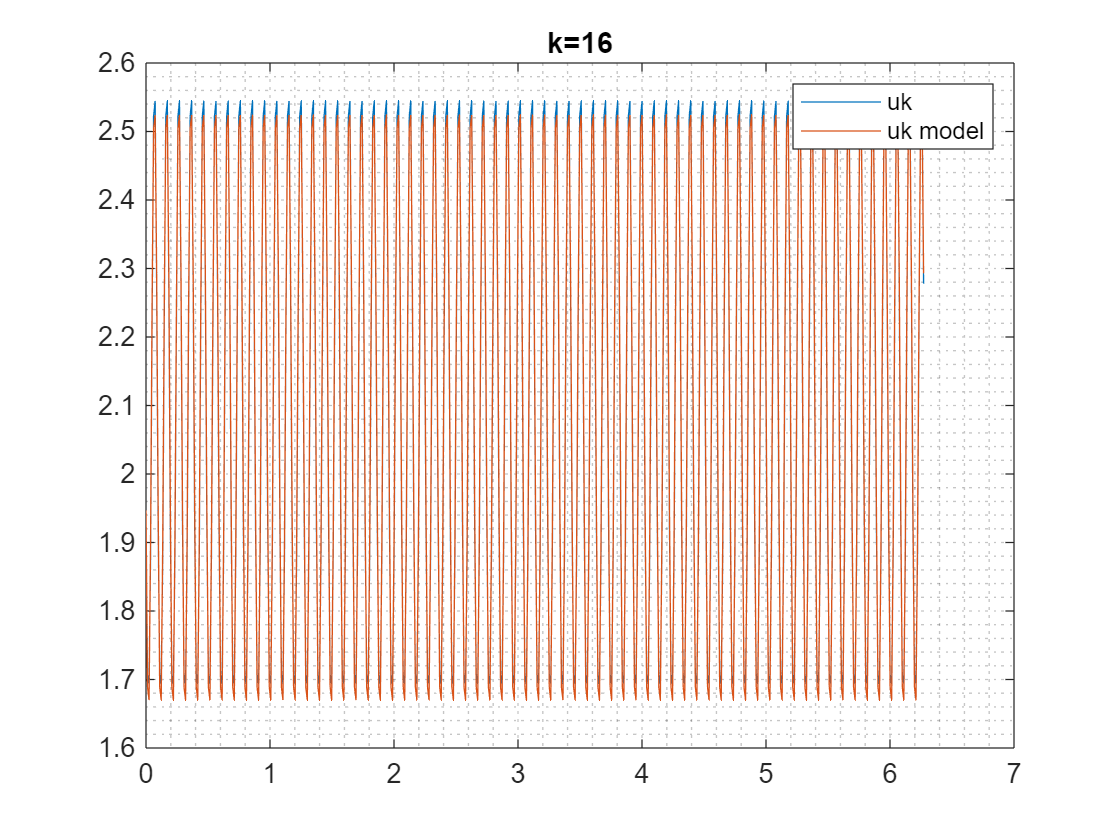

figure;hold on;
k=16;
u4=u(k+1,:);
u4model=diffusion_model([D_opt(k),E_opt(k),F_opt(k),G_opt(k)],x,params.dt*k, params.lambda);

plot(x,u4,'DisplayName','uk');
plot(x,u4model,'DisplayName','uk model');
%plot(x,smoothed(k+1,:),'DisplayName','smoothed k')

grid minor; box on;
legend;
title(strcat('k=',num2str(k)));

## 绘制参数曲线

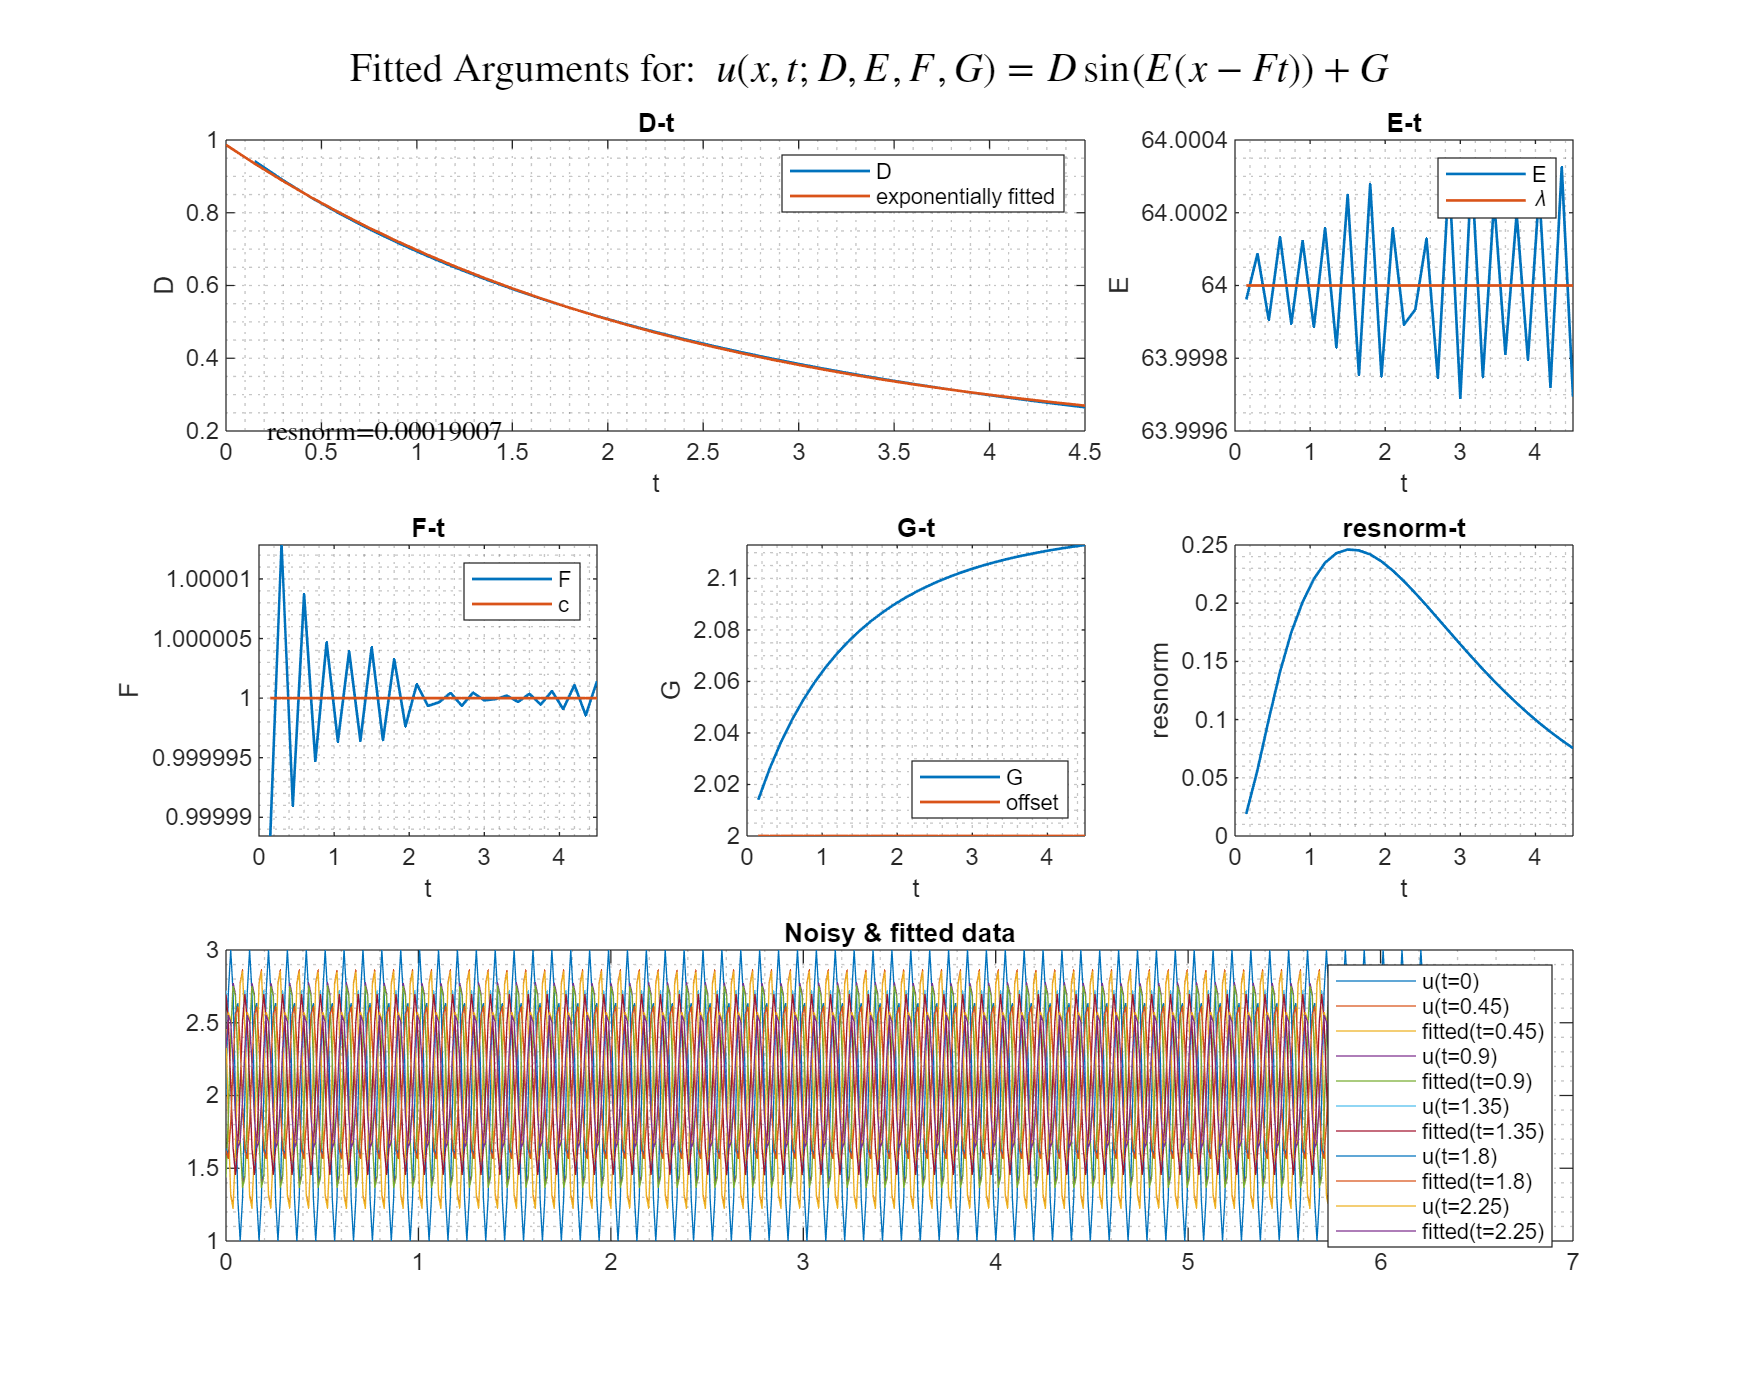

fig_args=figure(Position=[0,0,1280,1024]);
subplot(3,3,1:2);
hold on;
plot(t(2:end), D_opt, 'DisplayName','D','LineWidth',1.0);
plot(t,D_model(p_opt,t), 'DisplayName','exponentially fitted', 'LineWidth', 1.0);
text(0.2,0.2,strcat('resnorm=', num2str(resnorm_D)),'Interpreter','latex');
box on; grid minor;
legend;

xlabel('t');
ylabel('D');
title('D-t')

subplot(3,3,3);
plot(t(2:end),E_opt(1:end),LineWidth=1,DisplayName='E');
hold on;
plot(t(2:end),ones(1,length(t)-1)*params.lambda,DisplayName='\lambda',LineWidth=1);
legend;
xlabel('t');
ylabel('E');
title('E-t')
grid minor;

subplot(3,3,4);
plot(t(2:end),F_opt(1:end),LineWidth=1,DisplayName='F');
hold on;
plot(t(2:end),ones(1,length(t)-1)*params.c,DisplayName='c',LineWidth=1);
legend;
xlabel('t');
ylabel('F');
title('F-t')
grid minor;

subplot(3,3,5);
plot(t(2:end),G_opt(1:end),LineWidth=1,DisplayName='G');
hold on;
plot(t(2:end),ones(1,length(t)-1)*params.offset,DisplayName='offset',LineWidth=1);
legend('location','southeast')
xlabel('t');
ylabel('G');
title('G-t')
grid minor;

subplot(3,3,6);
plot(t(2:end),resnorms(1:end),LineWidth=1);
xlabel('t');
ylabel('resnorm');
title('resnorm-t')
grid minor;

subplot(3,3,7:9);
hold on;
title('Noisy & fitted data');
% plot first 1/3 of the timespan for n_plot evenly_stepped times.
n_plot = 4;
step=floor(params.nsteps / n_plot / 2);
for i=0:step:params.nsteps/2
    ui=u(i+1,:);
    plot(x,ui, 'DisplayName',strcat('u(t=',num2str(params.dt*i),')'));
    if i>0
        u_model = diffusion_model([D_opt(i),E_opt(i),F_opt(i),G_opt(i)],x, params.dt*(i), params.lambda);
        plot(x,u_model,'DisplayName',strcat('fitted(t=',num2str(params.dt*i),')'))
    end
end
grid minor; box on;
legend;

sgtitle(strcat('Fitted Arguments for: ',modelEq), Interpreter='latex')

### Save Figure

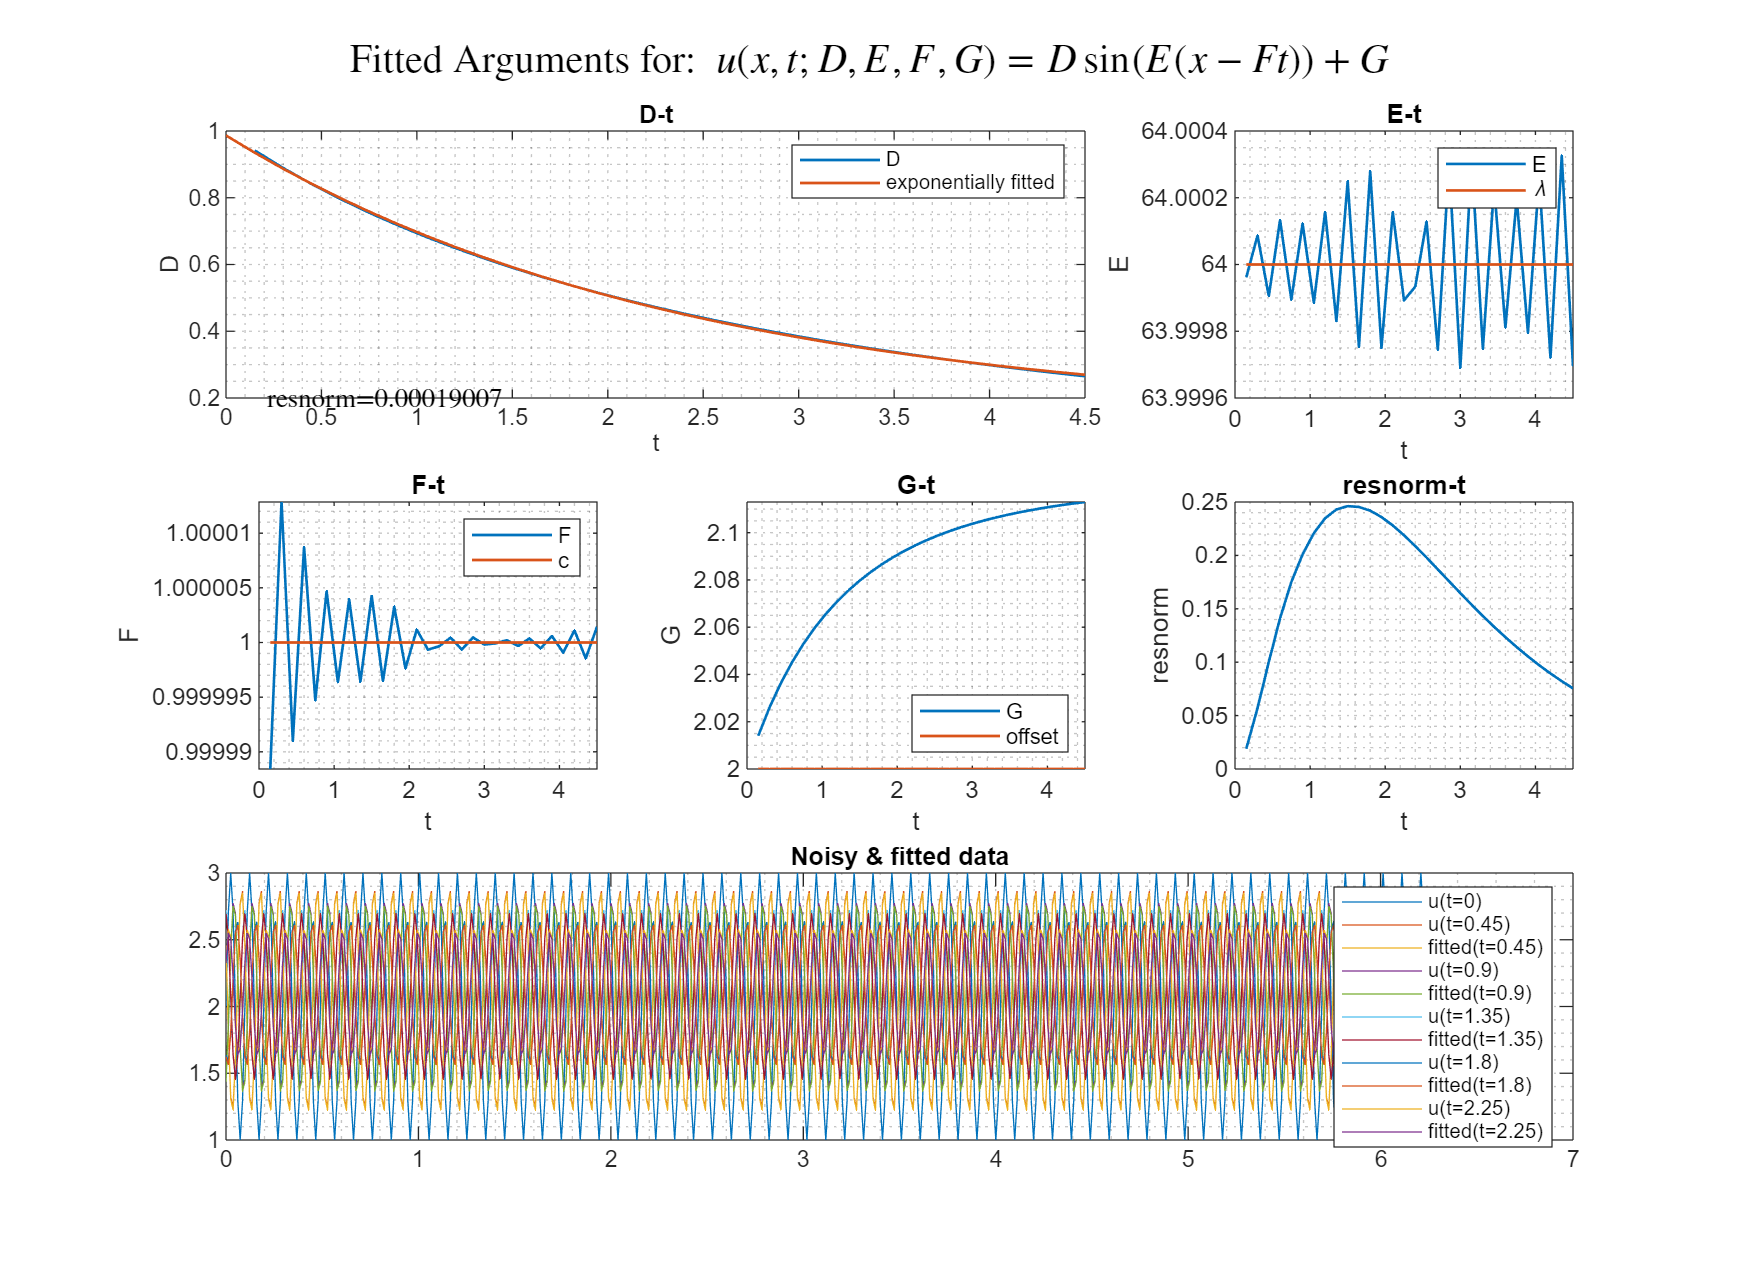

filename = strcat('result/',...
    noise_type_str(params.noise_type+1), num2str(params.noise_p),...
    '_lambda',num2str(params.lambda),...
    '_offset',num2str(params.offset),...
    '_dt', num2str(params.dt),...
    '_nqubits',num2str(params.nqubits));
savefig(fig_args, strcat(filename,'.fig'))
exportgraphics(fig_args, strcat(filename,'.pdf'));

## Save workspace

save(strcat(filename,'.mat'))

### Save modeling results

dlmwrite('result/ModelingResults.csv',...
    [params.c,params.L,params.lambda, params.offset, params.dt, params.nqubits, params.nsteps, params.noise_type, params.noise_p, P,Q,R,resnorm_D],...
    'delimiter',',','-append');

TODO: 只在大于0的部分拟合